## Plot fitted curves and dataset - Y25747 Fern

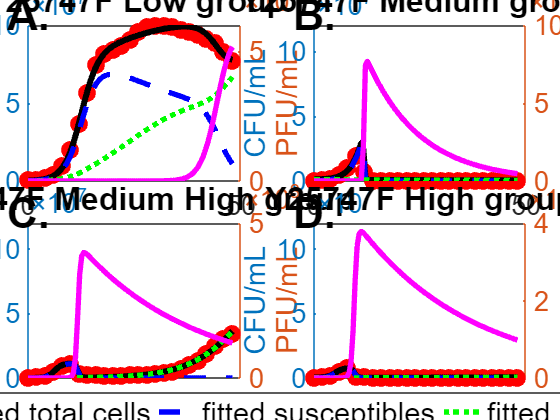

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Load fitted parameters Y3650F from mat file
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
load('fitted_param_Y25747F.mat','Y25747F_low',...
                                'Y25747F_medium',...
                                'Y25747F_medium_high',...
                                'Y25747F_high')

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Load the dataset from excel file
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

excelFileName = 'Y25747_Fern_dataset.xlsx'; 
Y25747F_grouped = readtable(excelFileName, 'Sheet', 'Y25747_Fern_Grouped',...
                            'VariableNamingRule', 'preserve');
% Extract growth data for 4 groups
time = downsample(Y25747F_grouped.Time,8)/60; % increment of 2 hours

data_low_mean = downsample(Y25747F_grouped.Low_Group_Mean*1E8,8);
data_low_std = downsample(Y25747F_grouped.Low_Group_Std*1E8,8);

data_medium_mean = downsample(Y25747F_grouped.Medium_Group_Mean*1E8,8);
data_medium_std = downsample(Y25747F_grouped.Medium_Group_Std*1E8,8);

data_medium_high_mean = downsample(Y25747F_grouped.Medium_High_Group_Mean*1E8,8);
data_medium_high_std = downsample(Y25747F_grouped.Medium_High_Group_Std*1E8,8);

data_high_mean = downsample(Y25747F_grouped.High_Group_Mean*1E8,8);
data_high_std = downsample(Y25747F_grouped.High_Group_Std*1E8,8);

% Calculated fitted curves for low group
tspan = linspace(time(1), time(end));
[T1, S1, R1, P1] = TSRP(Y25747F_low, tspan);
[T2, S2, R2, P2] = TSRP(Y25747F_medium, tspan);
[T3, S3, R3, P3] = TSRP(Y25747F_medium_high, tspan);
[T4, S4, R4, P4] = TSRP(Y25747F_high, tspan);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
h1 = subplot(2,2,1);

set(gca,'FontSize', 20, 'FontName', 'Arial')
ax.XAxis.LineWidth = 1.5;
ax.YAxis.LineWidth = 1.5;
yyaxis left

plot(time, data_low_mean,'.', 'MarkerSize',40,...
     'MarkerEdgeColor','red','Color','red'); hold on
plot(tspan, T1, 'k-', 'LineWidth', 4.5) % the fitted curve S + R
plot(tspan, S1, 'b--', 'LineWidth', 4) % fitted susceptibles S
plot(tspan, R1, 'g:', 'LineWidth', 4) % fitted resistants R
% ylim([0 1.2*10^8]);
xlabel('Hours','FontSize',22)
ylabel('CFU/mL','FontSize',22)
% set(gca, 'YScale', 'log')

yyaxis right
plot(tspan, P1, 'm-', 'LineWidth', 4) % fitted phage P
% ylim([1E0 1E12]);
% set(gca, 'YScale', 'log')
ylabel('PFU/mL','FontSize',22)

title('Y25747F Low group', 'FontSize', 24)
% Add 'A' label to top-left outside the plot
text(-0.1, 1.07, 'A.', 'Units', 'normalized', 'FontSize', 32,...
                                'FontWeight', 'bold', 'FontName', 'Arial')
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

h2 = subplot(2,2,2);

set(gca,'FontSize', 20, 'FontName', 'Arial')
ax.XAxis.LineWidth = 1.5;
ax.YAxis.LineWidth = 1.5;
yyaxis left

plot(time, data_medium_mean,'.', 'MarkerSize',40,...
     'MarkerEdgeColor','red','Color','red'); hold on
plot(tspan, T2, 'k-', 'LineWidth', 4.5) % the fitted curve S + R
plot(tspan, S2, 'b--', 'LineWidth', 4) % fitted susceptibles S
plot(tspan, R2, 'g:', 'LineWidth', 4) % fitted resistants R
ylim([0 1.2*10^8]);
xlabel('Hours','FontSize',22)
ylabel('CFU/mL','FontSize',22)
% set(gca, 'YScale', 'log')

yyaxis right
plot(tspan, P2, 'm-', 'LineWidth', 4) % fitted phage P
% ylim([1E0 1E12]);
% set(gca, 'YScale', 'log')
ylabel('PFU/mL','FontSize', 22)

title('Y25747F Medium group', 'FontSize', 24)
% Add 'B' label to top-left outside the plot
text(-0.1, 1.07, 'B.', 'Units', 'normalized', 'FontSize', 32,...
                               'FontWeight', 'bold', 'FontName', 'Arial')
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

h3 = subplot(2,2,3);

set(gca,'FontSize', 20, 'FontName', 'Arial')
ax.XAxis.LineWidth = 1.5;
ax.YAxis.LineWidth = 1.5;
yyaxis left

plot(time, data_medium_high_mean,'.', 'MarkerSize',40,...
     'MarkerEdgeColor','red','Color','red'); hold on
plot(tspan, T3, 'k-', 'LineWidth', 4.5) % the fitted curve S + R
plot(tspan, S3, 'b--', 'LineWidth', 4) % fitted susceptibles S
plot(tspan, R3, 'g:', 'LineWidth', 4) % fitted resistants R
ylim([0 1.2*10^8]);
xlabel('Hours','FontSize',22)
ylabel('CFU/mL','FontSize',22)
% set(gca, 'YScale', 'log')

yyaxis right
plot(tspan, P3, 'm-', 'LineWidth', 4) % fitted phage P
% ylim([1E0 1E12]);
% set(gca, 'YScale', 'log')
ylabel('PFU/mL','FontSize', 22)

title('Y25747F Medium High group', 'FontSize', 24)
% Add 'C' label to top-left outside the plot
text(-0.1, 1.07, 'C.', 'Units', 'normalized', 'FontSize', 32,...
                               'FontWeight', 'bold', 'FontName', 'Arial')
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

h4 = subplot(2,2,4);

set(gca,'FontSize', 20, 'FontName', 'Arial')
ax.XAxis.LineWidth = 1.5;
ax.YAxis.LineWidth = 1.5;
yyaxis left

plot(time, data_high_mean,'.', 'MarkerSize',40,...
     'MarkerEdgeColor','red','Color','red'); hold on
plot(tspan, T4, 'k-', 'LineWidth', 4.5) % the fitted curve S + R
plot(tspan, S4, 'b--', 'LineWidth', 4) % fitted susceptibles S
plot(tspan, R4, 'g:', 'LineWidth', 4) % fitted resistants R
ylim([0 1.2*10^8]);
xlabel('Hours','FontSize',22)
ylabel('CFU/mL','FontSize',22)
% set(gca, 'YScale', 'log')

yyaxis right
plot(tspan, P4, 'm-', 'LineWidth', 4) % fitted phage P
% ylim([1E0 1E12]);
% set(gca, 'YScale', 'log')
ylabel('PFU/mL','FontSize', 22)

title('Y25747F High group', 'FontSize', 24)
% Add 'D' label to top-left outside the plot
text(-0.1, 1.07, 'D.', 'Units', 'normalized', 'FontSize', 32,...
                               'FontWeight', 'bold', 'FontName', 'Arial')
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Add a common legend at the bottom of the figure
lgd = legend('growth dataset','fitted total cells', 'fitted susceptibles',...
       'fitted resistants','fitted phage');
lgd.FontSize = 22;
lgd.Orientation = 'horizontal';
lgd.Position = [0.5, 0.02, 0, 0];
lgd.Units = 'normalized';

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
set(0,'Units','normalized')
set(h4,'position',[.56 .1 .38 .37])
set(h3,'position',[.05 .1 .38 .37])
set(h2,'position',[.56 .57 .38 .37])
set(h1,'position',[.05 .57 .38 .37])
set(gcf, 'PaperSize', [20 16], 'PaperPosition', [0 0 20 16])
print('Y25747F_fitted_curves','-djpeg','-r300')

%%%%%%%%%%%%%%%%%%%%%%%%%%%%


## Compute total host cells, susceptibles, and resistants for 1-species-1-phage model

function [T,S,R,P] = TSRP(para_fit,t)
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Pre-estimate parameters for the model
    K = 10^9; % CFU/mL
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Fitting parameters for the model
    r = para_fit(1);
    a = para_fit(2);
    a_ss = para_fit(3);
    a_rr = para_fit(4);
    delta = para_fit(5);
    gamma = para_fit(6);
    phi = para_fit(7);
    beta = para_fit(8);
    m = para_fit(9);
    S0 = para_fit(10);
    R0 = para_fit(11);
    P0 = para_fit(12);

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Compute the total host cells from the model
    initial_value = [S0;R0;P0];
    p = [r,a,a_ss,a_rr,K,delta,gamma,phi,beta,m];
    func = @one_species_one_phage;
    [~,y] = ode15s(@(r,y) func(r,y,p),t,initial_value);
    T = y(:,1) + y(:,2);
    S = y(:,1);
    R = y(:,2);
    P = y(:,3);
end

## Compute total host cells for 1-species-1-phage model

function T = total_host_cells(para_fit,t)
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Pre-estimate parameters for the model
    K = 10^9; % CFU/mL
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Fitting parameters for the model
    r = para_fit(1);
    a = para_fit(2);
    a_ss = para_fit(3);
    a_rr = para_fit(4);
    delta = para_fit(5);
    gamma = para_fit(6);
    phi = para_fit(7);
    beta = para_fit(8);
    m = para_fit(9);
    S0 = para_fit(10);
    R0 = para_fit(11);
    P0 = para_fit(12);

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    % Compute the total host cells from the model
    initial_value = [S0;R0;P0];
    p = [r,a,a_ss,a_rr,K,delta,gamma,phi,beta,m];
    func = @one_species_one_phage;
    [~,y] = ode15s(@(r,y) func(r,y,p),t,initial_value);
    T = y(:,1) + y(:,2);
end

## Vector field for 1-species-1-phage model

function dy = one_species_one_phage(t,y,p)
    %%%%%%%%%%%%%%%
    r = p(1); % growth rate of S in the absence of P and R
    a = p(2); % interspecific competition coefficient of S and R
    a_ss = p(3); % intraspecific competition coefficient of S
    a_rr = p(4); % intraspecific competition coefficient of R
    K = p(5); % system-wide carrying capacity
    delta = p(6); % rate of resistance acquisition
    gamma = p(7); % fitness cost of phage resistance (rel. to parental phenotype)
    phi = p(8); % the adsorption rate of P when attaching to S
    beta = p(9); % burst size of phage P when infecting S
    m = p(10); % decay rate of phage P
    %%%%%%%%%%%%%%%
    dy = zeros(3,1);
    dy(1) = r*y(1)*(1-(a_ss*y(1) + a*y(2))/K) - delta*y(1) - phi*y(3)*y(1);
    dy(2) = gamma*r*y(2)*(1-(a*y(1) + a_rr*y(2))/K) + delta*y(1);
    dy(3) = beta*phi*y(3)*y(1) - m*y(3);
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %  y(1) represents the population density of phage-susceptible bacteria S
    %  y(2) represents the population density of phage-resistant bacteria R
    %  y(3) represents the population density of phage P
    %  p = [r,a,a_ss,a_rr,K,delta,gamma,phi,beta,m]
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%
end